## The impact of the EU-ETS on unemployment in France

### 0. Housekeeping

clear;
close all;

### 1. Data Importation 

Import Data Series:

- `GDP: OECD/QNA/FRA.B1_GE.CQRSA.Q`

- `Inflation: OECD/QNA/FRA.B1_GE.DNBSA.Q`

- `Unemployment: OECD/MEI/FRA.LRUN64TT.STSA.Q`

- `Carbon emissions: Eurostat/sdg_13_10/A.GHG.TOTX4_MEMONIA.T_HAB.FR`

`Every serie is SA.`

% GDP, deflator, unemployment
[output1,~,T1] = call_dbnomics('OECD/QNA/FRA.B1_GE.CQRSA.Q','OECD/QNA/FRA.B1_GE.DNBSA.Q', 'OECD/MEI/FRA.LRUN64TT.STSA.Q');

% Carbon emissions
[output2,~,T2] = call_dbnomics('Eurostat/sdg_13_10/A.GHG.TOTX4_MEMONIA.T_HAB.FR');

% Carbon prices
tt_import = readtimetable("carbon_prices_062009_122019.xlsx");


### 2. Data treatment

Retime emissions and carbon prices to quarterly data

% Carbon emissions
dates = datetime(output2(:,1), 'ConvertFrom', 'datenum');
values = output2(:,2);
tt = timetable(dates, values);

ttQ = retime(tt, 'quarterly', 'linear');
output2Q = [datenum(ttQ.dates), ttQ.values];

% Carbon prices
carbon_prices = retime(tt_import(:,4),"quarterly","mean");

Merge datasets

output = merged_output(output1, output2Q);

Drop Na values and get index

idx = find(~isnan(sum(output(:,2:end),2)));
output = output(idx,:);
T = T1(idx);

Normalize to 2015 prices

id2015 = find(T==2015);
def = output(:,3)/output(id2015,3);

### 3. Create variables of interest

gy_obs  = diff(log(output(:,2)./(def))); % Output growth
pi_obs  = diff(log(def)); % Inflation growth
u_obs = diff(log(output(:,4))); % Unemployment growth
ges_obs = diff(log(output(:,5))); % Emission growth
T = T(2:end);

### 4. Test stationnarity

1 means that we reject null hypothesis (ADF = 1 => stationnarity ; KPSS = 1 => non-stationnarity)

GDP growth: stationnary

[h,pValue,stat,cValue] = adftest(gy_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -11.3673

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(gy_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0146

cValue = 0.1460

Inflation: non-stationnary

[h,pValue,stat,cValue] = adftest(pi_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -9.1523

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(pi_obs) %pval = 1% => probablement car tendance haussière en fin de série mais si on s'arrête fin 2019, le problème devrait être réglé

h = logical
   0


pValue = 0.1000

stat = 0.0765

cValue = 0.1460

Unemployment: non-stationnary

[h,pValue,stat,cValue] = adftest(u_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -9.5549

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(u_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0779

cValue = 0.1460

Carbon emissions:

[h,pValue,stat,cValue] = adftest(ges_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -3.4620

cValue = -1.9446

[h,pValue,stat,cValue] = kpsstest(ges_obs)

h = logical
   0


pValue = 0.1000

stat = 0.0669

cValue = 0.1460

### 5. Plot variables

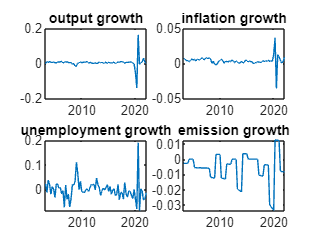

figure;
subplot(2,2,1)
plot(T,gy_obs)
xlim([min(T) max(T)]);
title('output growth')
subplot(2,2,2)
plot(T,pi_obs)
xlim([min(T) max(T)]);
title('inflation growth')
subplot(2,2,3)
plot(T,u_obs)
xlim([min(T) max(T)]);
title('unemployment growth')
subplot(2,2,4)
plot(T,ges_obs)
xlim([min(T) max(T)]);
title('emission growth')

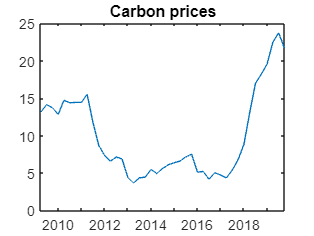


figure;
plot(carbon_prices.dates,carbon_prices.pe_obs2)
title('Carbon prices')

### 6. Save variables in a matrix 

save myobs T gy_obs pi_obs u_obs ges_obs;